First script to start the transistion in data format for EEG recorder.

The aim is to follow the data structure of EEGlab or Fieldtrip. 

More inforamtion on the Fieldtrip format can be found on:

[https://www.fieldtriptoolbox.org/faq/how_can_i_import_my_own_dataformat/](https://www.fieldtriptoolbox.org/faq/how_can_i_import_my_own_dataformat/)

The data should be a MATLAB struct with the following fields:

**data.label**          % cell-array containing strings, Nchan*1

**data.fsample**     % sampling frequency in Hz, single number

**data.trial**            % cell-array containing a data matrix for each trial (1*Ntrial), each data matrix is a Nchan*Nsamples matrix

**data.time  **         % cell-array containing a time axis for each trial (1*Ntrial), each time                      axis is a 1*Nsamples vector

**data.trialinfo **     % this field is optional, but can be used to store trial-specific information, such as condition numbers, reaction times, correct responses etc. The dimensionality is Ntrial*M, where M is an arbitrary number of columns.

**data.sampleinfo** % optional array (Ntrial*2) containing the start and end sample of each trial

Attempt at 'import' function for the new format:

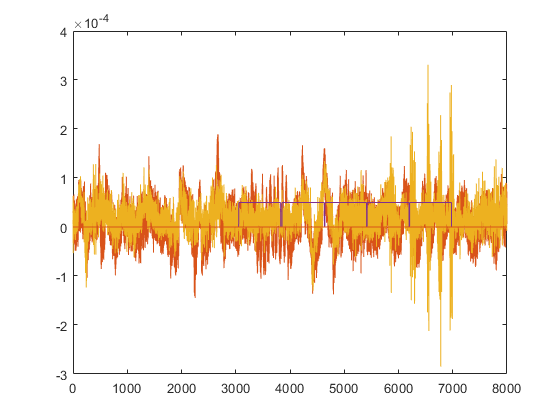

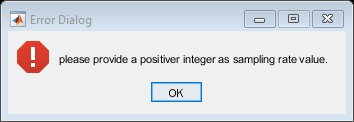

Brace indexing is not supported for variables of this type.

Error in new_data_format>import_data (line 65)
if strcmp(opts{3}{:}, opts{4}{:})

[filename, filepath]= uigetfile();
load([filepath filename]);
old_data = data;
clear data
plot(old_data(:,1:2))
hold on
plot(old_data(:,9:14)/1e5)
data = import_data(old_data);

function data = import_data(old_data)
% this function takes a plain matrix and converts it to the new Fieldtrip
% like format by running the user through a few questions

% check if the input data is a plain matrix
if ~ismatrix(old_data)
    warndlg('The selected file does not contain a simple matrix and therefore can not be imported', 'Wrong data type')
   return
end
data.trial = old_data';

dlgtitle = 'Provide information on your data';
dlgpromt = { ...
    'what is the sampling rate of the data?'; ...
    'What are the names of the channels?'; ...
    'what do the rows represent?'; ...
    'What do the columns represent?' ...
    };

formats = struct('type', {}, 'style', {}, 'items', {}, 'format', {}, 'limits', {}, 'size', {});

formats(1,1).type   = 'edit';
formats(1,1).format = 'integer';
formats(1,1).style  = 'edit';
formats(1,1).size   = [100 20];

formats(2,1).type   = 'edit';
formats(2,1).format = 'text';
formats(2,1).style  = 'edit';
formats(2,1).size   = [600 20];

formats(3,1).type   = 'list';
formats(3,1).format = 'text';
formats(3,1).style  = 'popupmenu';
formats(3,1).items  = {'samples', 'channels'};

formats(4,1).type  = 'list';
formats(4,1).format = 'text'; 
formats(4,1).style  = 'popupmenu';
formats(4,1).items  = {'samples', 'channels'};

defaultAnswers = {256;'';'samples';'channels'};

opts = inputsdlg(dlgpromt, dlgtitle, formats, defaultAnswers);

%% input checks

if isempty(opts{1})
    errordlg('please provide a sampling rate.')
elseif ~isnumeric(opts{1})
    errordlg('please provide a numeric value for the sampling rate.')
elseif opts{1} <= 0 || ~isinteger(opts{1})
    errordlg('please provide a positiver integer as sampling rate value.')
end

% check if the data dimensions are different
if strcmp(opts{3}{:}, opts{4}{:})
    warndlg('The dimensions of the data can not be the same.')
    return
elseif strcmp(opts{3}{:}, 'samples') && strcmp(opts{4}{:},'channels')
    % use the data as it is
    data.trial = old_data;
elseif strcmp(opts{3}{:}, 'channels') && strcmp(opts{4}{:},'samples')
    % transpose the data to match the new format
    data.trial = old_data';
else
    % this should not be able to happen
    warndlg('Hmm something strange happened.')
end
    

data.fsample    = opts{1};
data.labels     = strsplit(opts{2});
data.time       = (0:size(data.trial,1)-1) / data.fsample;
data.sampleinfo = [1 size(data.trial,1)];

% function end
end

